    cd(fileparts(matlab.desktop.editor.getActiveFilename))
    pwd

ans = '/Users/ellarond/Dropbox/Papers/Neural plate fate choice/v3.0/Code'

    addpath("utils")
    plot_dir = fullfile('in_toto_tracking', 'Plots');
    if ~isfolder(plot_dir)
        mkdir(plot_dir);
    end
    filename = '2022-01-08_Sox19xShh_2ss_E1-01_T01.czi';
    pathname = 'in_toto_tracking'

pathname = 'in_toto_tracking'

    
    exp_dir = pathname;
    filename_prefix = filename(1:end - 8);
    data_files = dir(fullfile(pathname, 'map_data', [filename_prefix, '*_data.mat']));
    num_timepoints = length(data_files);
    
    filename_parts = split(filename, '_');
    exp_prefix = join(filename_parts(1:end-1), '_');

    %% original spot assignments
    filename = '2022-01-08_Sox19xShh_2ss_E1-01_trackmate_coords_v_time.mat'

filename = '2022-01-08_Sox19xShh_2ss_E1-01_trackmate_coords_v_time.mat'

    temp = load(fullfile(pathname, filename));
    coords_data = temp.coordinates;
    tracks_info = zeros(size(coords_data, 1), num_timepoints);
    for tp = 1:num_timepoints
        idx = find(~ismember(squeeze(coords_data(:, tp, 1:3)), [0 0 0], 'rows'));
        tracks_info(idx, tp) = 1:length(idx);
    end
    original_tracks_info = tracks_info;

    % modified tracks
     filename = '2022-01-08_Sox19xShh_2ss_E1-01_Kalman_trackmate_coords_v_time.mat'

filename = '2022-01-08_Sox19xShh_2ss_E1-01_Kalman_trackmate_coords_v_time.mat'

     temp = load(fullfile(pathname, filename));
     new_coords_data = temp.coordinates;
     new_tracks_info = zeros(size(new_coords_data, 1), num_timepoints);
     for tp = 1:num_timepoints
         %tp
         idx = find(~ismember(squeeze(new_coords_data(:, tp, 1:3)), [0 0 0], 'rows'));
         [~, new_pos] = ismember(squeeze(new_coords_data(idx, tp, 1:3)), squeeze(coords_data(:, tp, 1:3)), 'rows');

        new_tracks_info(idx(find(new_pos)), tp) = original_tracks_info(nonzeros(new_pos), tp);
     end
     tracks_info = new_tracks_info;

     
    % mapped_points is tracks x tp [x, y, z]
    mapped_points = zeros(size(tracks_info, 1), size(tracks_info, 2), 3);
    world_coordinates = zeros(size(tracks_info, 1), size(tracks_info, 2), 3);

    % axis endpoints [R, C, Z]
    axis_endpoints = zeros(size(tracks_info, 2), 3);
    for tp = 1:num_timepoints
        if isfile(fullfile(exp_dir, 'map_data', [filename_prefix, '_T', sprintf('%02d', tp), '_data_AS_adj.mat']))
            vars = load(fullfile(exp_dir, 'map_data', [filename_prefix, '_T', sprintf('%02d', tp), '_data_AS_adj.mat']));
        else
            vars = load(fullfile(exp_dir, 'map_data', [filename_prefix, '_T', sprintf('%02d', tp), '_data.mat']));
        end
        map = vars.save_data.map;
        valid_filt_tracks_idx = find(tracks_info(:, tp));

        axis_endpoints(tp, :) = [vars.save_data.Rmarks(end), vars.save_data.Cmarks(end), vars.save_data.Zmarks(end)];
            
        valid_segments = unique(nonzeros(vars.save_data.curated_seg_im));
        if length(valid_filt_tracks_idx) > length(valid_segments)
            missing_segments = find(~ismember(tracks_info(valid_filt_tracks_idx, tp), valid_segments))
            for ms = missing_segments'
                map = cat(1, map(1:ms-1, :), [0 0 0 0], map(ms:end, :));
            end
        end
        mapped_points(valid_filt_tracks_idx, tp, 1:3) = map(tracks_info(valid_filt_tracks_idx, tp), [1, 2, 4]);
        writematrix(map, fullfile(exp_dir, [filename_prefix, '_T', sprintf('%02d', tp), '_NPcoordinates.xlsx']));

        tp_world_coordinates = csvread(fullfile(exp_dir, [filename_prefix, '_T', sprintf('%02d', tp), '_TMcoordinates.csv']), 1, 0);
        world_coordinates(valid_filt_tracks_idx, tp, 1:3) = tp_world_coordinates(tracks_info(valid_filt_tracks_idx, tp), 1:3);
        %mapped_points(mapped_points(:, 1) > 0) = -mapped_points(mapped_points(:, 1) > 0);
    end

 % only keep tracks longer than a certain length
 TRK_LENGTH_THRES = 5;
 max_y = max(squeeze(mapped_points(:, :, 2)), [], 2);
 filt_track_idx = find(sum(logical(tracks_info), 2) > TRK_LENGTH_THRES & max_y > 0);
 filt_tracks_info = tracks_info(filt_track_idx, :);


    interp_mapped_points = mapped_points;
    timepoints = 1:num_timepoints;
    for n = 1:size(mapped_points, 1)

        mapped_points_n = squeeze(mapped_points(n, :, :));
        gaps = find(ismember(mapped_points_n, [0 0 0], 'rows'))';
        temp = zeros(1,  size(mapped_points_n, 1));
        temp(gaps) = 1;
        gaps_end = find(diff([0, temp, 0]) == -1);
        gaps_start = find(diff([0, temp, 0]) == 1);
        gap_length = gaps_end - gaps_start;
        gaps_to_fill = []; %gaps_start(find(gap_length <= 3)):(gaps_end(find(gap_length <= 3)) - 1);

        for k = 1:length(gap_length)
            if gap_length <= 3
                gaps_to_fill = [gaps_to_fill, gaps_start(k):gaps_end(k) - 1];
            end
        end

        if ~isempty(gaps_to_fill)
            for dim = 1:3
                % gaps can be due to gaps in tracking as well as mapping
                interp_mapped_points(n, gaps_to_fill, dim) = interp1(timepoints(find(mapped_points(n, :, dim))), nonzeros(mapped_points(n, :, dim)), gaps_to_fill);
            end
        end

        remaining_gaps = find(ismember(squeeze(interp_mapped_points(n, :, :)), [0 0 0], 'rows'))';

        interp_mapped_points(n, remaining_gaps, :) = NaN(length(remaining_gaps), 3);
        world_coordinates(n, remaining_gaps, :) = NaN(length(remaining_gaps), 3);


    end

        tot_tracks = size(filt_track_idx, 1);
        t_id=80;
        trn = filt_track_idx(t_id)

trn = 453

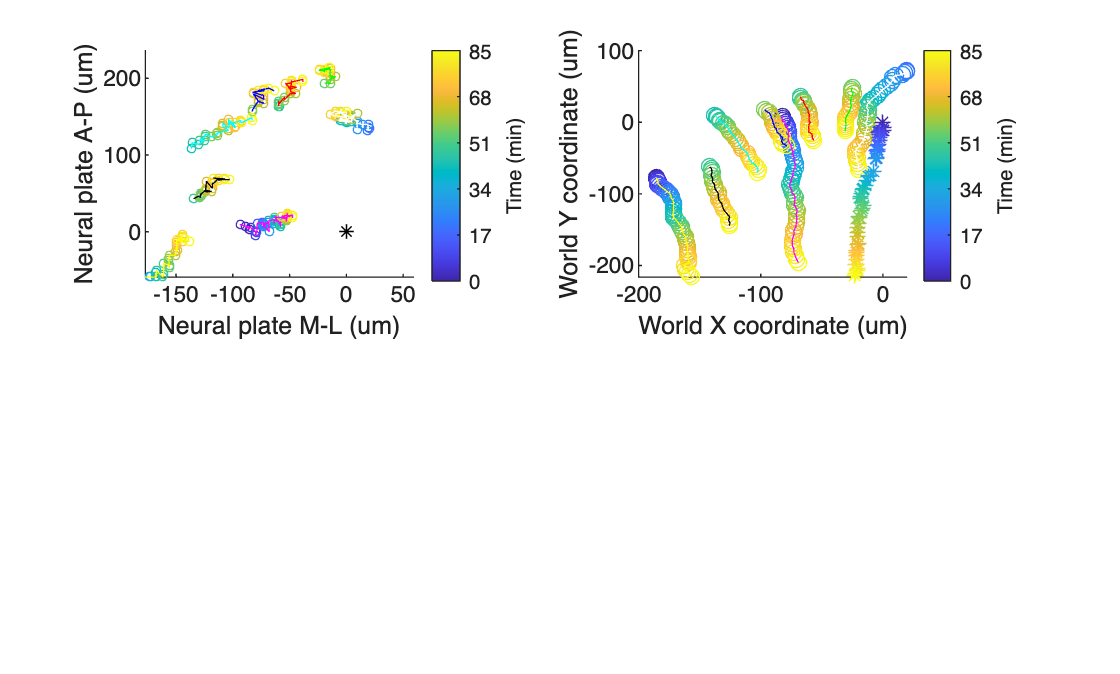

        track_name = [5300, 7674, 4023, 7933, 8162, 8244, 7930, 6631];
        line_colors = colorcube(length(track_name));
        trn = track_name - 4021;
        f = figure;
        start_tp = 3;
        timepoints  = start_tp:size(filt_tracks_info, 2);
        spot_colors = parula(length(timepoints));
        scale_factor = 0.59;

        subplot(2, 2, 1); hold on;
        scatter(scale_factor*interp_mapped_points(trn, timepoints, 1), scale_factor*interp_mapped_points(trn, timepoints, 2), 10, spot_colors);
        c = colorbar('TickLabels', string(5100*(0:0.2:1)/60)); 
        c.Label.String = 'Time (min)';
        scatter(0, 0, 30, [0 0 0], '*');

        for k = 1:length(track_name)
            plot(scale_factor*interp_mapped_points(trn(k), timepoints, 1), scale_factor*interp_mapped_points(trn(k), timepoints, 2), 'Marker', 'none', 'Color', line_colors(k, :));
        end
        xlim(scale_factor*[-300 100]);
        ylim(scale_factor*[-100 400]);
        xlabel('Neural plate M-L (um)'); ylabel('Neural plate A-P (um)');


        subplot(2, 2, 2); hold on;
        start_y = 0.59*axis_endpoints(start_tp, 1);
        start_x = 0.59*axis_endpoints(start_tp, 2);
        scatter(world_coordinates(trn, timepoints, 1) - start_x, start_y - world_coordinates(trn, timepoints, 2), [], spot_colors)
        scatter(0.59*axis_endpoints(timepoints, 2) - start_x, start_y - 0.59*axis_endpoints(timepoints, 1), [], spot_colors, '*')
        c = colorbar('TickLabels', string(5100*(0:0.2:1)/60)); 
        c.Label.String = 'Time (min)';
        for k = 1:length(track_name)
            plot(world_coordinates(trn(k), timepoints, 1) - start_x, start_y - world_coordinates(trn(k), timepoints, 2), 'Marker', 'none', 'Color', line_colors(k, :));
        end
        xlabel('World X coordinate (um)'); ylabel('World Y coordinate (um)');

        %saveas(f, fullfile(exp_dir, 'E1_world_vs_NP_track_examples.svg'))

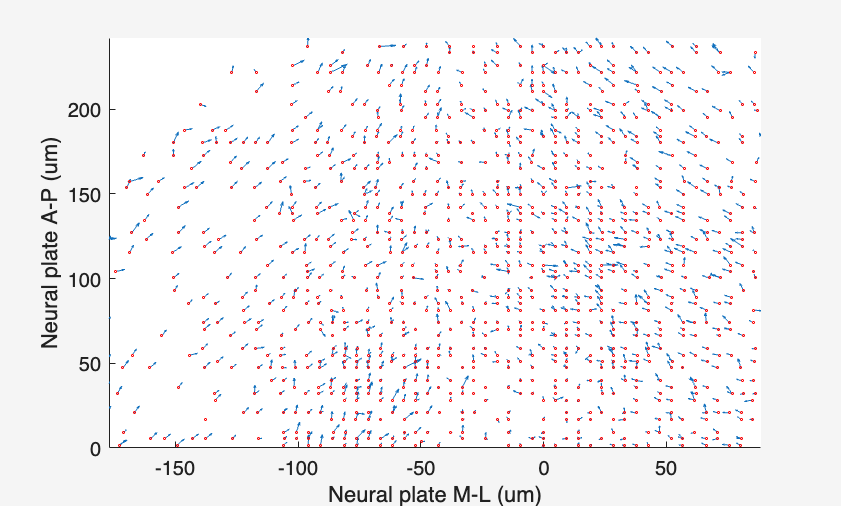

plot_tracks = filt_track_idx;

mean_z_pos = nanmean(interp_mapped_points(plot_tracks, :, 3), 2);
SURFACE_Z_THRES = 5; 
deep_plot_tracks = plot_tracks(mean_z_pos > SURFACE_Z_THRES);
map_data = interp_mapped_points(deep_plot_tracks, :, :);
disp = diff(map_data, 1, 2);
disp = cat(2, zeros(size(disp, 1), 1, 3), disp);
INT_WINDOW = 2;
cum_disp = zeros(size(disp, 1), num_timepoints - INT_WINDOW, 3);
for col = 1:(num_timepoints - INT_WINDOW)
    cum_disp(:, col, :) = sum(disp(:, col:col + INT_WINDOW, :), 2);
end

tracks_to_plot = 1:size(map_data, 1); %randsample(size(map_data, 1), 900); %
FIRST_TP = 40; LAST_TP = 51;
mean_disp = mean(cum_disp(:, FIRST_TP:LAST_TP, :), 2, 'omitnan');
mean_disp(abs(mean_disp) > 20) = nan;


VECTOR_SCALE = 1;
PLOT_TP = LAST_TP; %ceil(mean(FIRST_TP, LAST_TP));

tracks_data_forUI = struct;
tracks_data_forUI.map_data = scale_factor*map_data;
tracks_data_forUI.tp = PLOT_TP;
tracks_data_forUI.plotted_tracks_idx = deep_plot_tracks;
tracks_data_forUI.tracks_to_plot = tracks_to_plot;
tracks_data_forUI.mean_disp = scale_factor*mean_disp;
tracks_data_forUI.VECTOR_SCALE = VECTOR_SCALE;

f3 = plot_quiver_with_clickresponse(tracks_data_forUI);
xlim(scale_factor*[-300 150]); ylim(scale_factor*[0 410]);
xlabel('Neural plate M-L (um)'); ylabel('Neural plate A-P (um)');

%saveas(f3, fullfile(exp_dir, 'Plots', 'E1_raw_quiver.svg'));

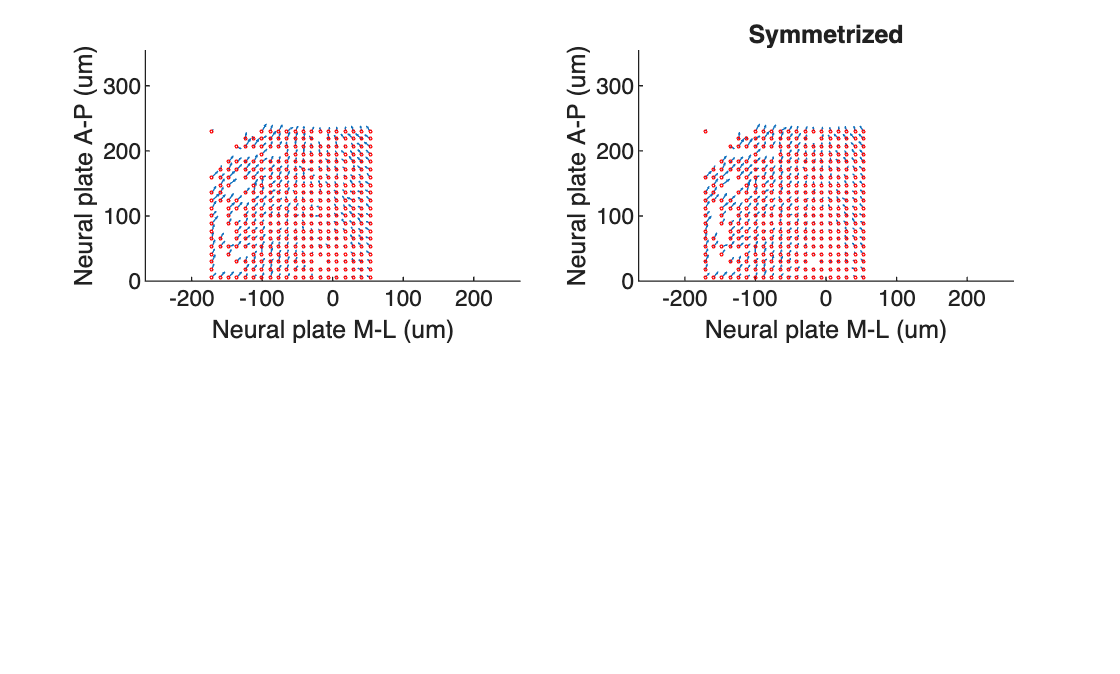

limits_x = [-300 300]; limits_y = [0 400];
points_cloud_image = zeros(limits_x(2) - limits_x(1), limits_y(2) - limits_y(1));
for k = 1:size(map_data, 1)
    if ~isnan(mean_disp(k, 1)) && ~isnan(mean_disp(k, 2))
        c = uint16(min(max(1, map_data(k, PLOT_TP, 1) - limits_x(1)), size(points_cloud_image, 2)));
        r = uint16(min(max(1, limits_y(2) - map_data(k, PLOT_TP, 2)), size(points_cloud_image, 1)));

        if points_cloud_image(r, c) == 0
            points_cloud_image(r, c) = k;
        else
            points_cloud_image(r + 1, c + 1) = k;
        end
    end
end
%figure; imshow(points_cloud_image, [0 1]);


avg_grid_data = []; 
avg_disp_on_grid = [];
spacing = 20;
all_points = [];
f2 = figure; hold on;
ax1 = subplot(2, 2, 1); hold on;
for r = 1:spacing:size(points_cloud_image, 1) - spacing
    for c =  1:spacing:size(points_cloud_image, 2) - spacing

        point_idx = nonzeros(unique(points_cloud_image(r:r+spacing, c:c+spacing)));
        all_points = cat(1, all_points, point_idx);
        if length(~isnan(mean_disp(point_idx, 1))) >= 1
            avg_grid_data(end + 1, 1:2) = [c - 1 + spacing/2 + limits_x(1), limits_y(2) - (r - 1  + spacing/2)];
            avg_disp_on_grid(end + 1, 1:2) = [nanmean(mean_disp(point_idx, 1, 1)), nanmean(mean_disp(point_idx, 1, 2))];
        end
    end
end

%figure; hold on;
quiver(scale_factor*avg_grid_data(:, 1), scale_factor*avg_grid_data(:, 2), avg_disp_on_grid(: , 1), avg_disp_on_grid(: , 2), 1);
plot(scale_factor*avg_grid_data(:, 1), scale_factor*avg_grid_data(:, 2), 'ro', 'MarkerSize', 1);
xlim(scale_factor*[-300 150])
ylim(scale_factor*[0 410])
xlabel('Neural plate M-L (um)'); ylabel('Neural plate A-P (um)');


% symmetrize
sym_avg_grid_data = avg_grid_data;
sym_avg_disp_on_grid = avg_disp_on_grid;
for p = 1:size(avg_grid_data, 1)
    reflected_pt = find(ismember(sym_avg_grid_data, [-1*sym_avg_grid_data(p, 1), sym_avg_grid_data(p, 2)], 'rows'));
    if ~isempty(reflected_pt)
        sym_avg_disp_on_grid(p, :) = mean(cat(1, sym_avg_disp_on_grid(p, :), [-1*sym_avg_disp_on_grid(reflected_pt, 1), sym_avg_disp_on_grid(reflected_pt, 2)]), 'includenan');
    end
end

ax2 = subplot(2, 2, 2); hold on;
quiver(scale_factor*sym_avg_grid_data(:, 1), scale_factor*sym_avg_grid_data(:, 2), sym_avg_disp_on_grid(: , 1), sym_avg_disp_on_grid(: , 2), 1);
plot(scale_factor*sym_avg_grid_data(:, 1), scale_factor*sym_avg_grid_data(:, 2), 'ro', 'MarkerSize', 1);
title('Symmetrized')
xlim(scale_factor*[-300 150])
ylim(scale_factor*[0 410])
xlabel('Neural plate M-L (um)'); ylabel('Neural plate A-P (um)');

%saveas(f2, fullfile(exp_dir, 'Plots', 'E1_grid_averaged_tracks.svg'))
% rescale axes for overlay
axes(ax1);
xlim(scale_factor*[-450 450])
ylim(scale_factor*[0 600])

axes(ax2);
xlim(scale_factor*[-450 450])
ylim(scale_factor*[0 600])


%saveas(f2, fullfile(exp_dir, 'Plots', 'E1_grid_averaged_for_overlay.svg'))

% isolate points that lie on her3 domain
ch = 3;
post_shift = -50;
scale_factor = 1;
pathname = 'TF_maps'

pathname = 'TF_maps'

filename = '3F_map_avg.mat'

filename = '3F_map_avg.mat'

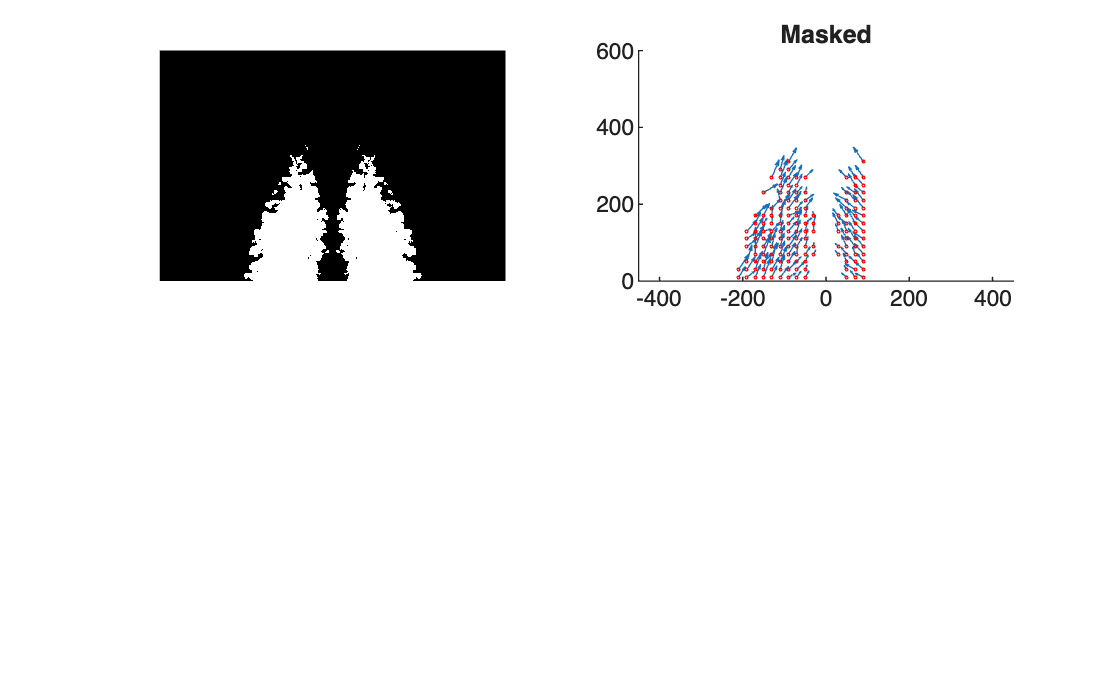

gene_name = filename(1:(strfind(filename, '_map') - 1));
temp = load(fullfile(pathname, filename));
map_avg = temp.map_avg;
mean_map = map_avg.(['channel', num2str(ch)]).mean_map;
gene_mask = 0*mean_map;
gene_mask((abs(post_shift) + 1):end, :) = mean_map(1:(end - abs(post_shift)), :);
thres = 0.15;
gene_mask(gene_mask > thres) = 1;
gene_mask(gene_mask <= thres) = 0;
%gene_mask = imopen(gene_mask, strel(10));

[pos_R, pos_C] = ind2sub(size(gene_mask), find(gene_mask));
rc_grid_data = 0*sym_avg_grid_data;
rc_grid_data(:, 2) = sym_avg_grid_data(:, 1) + size(gene_mask, 2)/2;
rc_grid_data(:, 1) = size(gene_mask, 1) - sym_avg_grid_data(:, 2);

masked_idx = find(ismember(rc_grid_data, [pos_R, pos_C], 'rows'));
f3 = figure; 
subplot(2, 2, 1); imshow(gene_mask, []);
ax2 = subplot(2, 2, 2); hold on;
quiver(scale_factor*sym_avg_grid_data(masked_idx, 1), scale_factor*sym_avg_grid_data(masked_idx, 2), sym_avg_disp_on_grid(masked_idx , 1), sym_avg_disp_on_grid(masked_idx , 2), 2);
plot(scale_factor*sym_avg_grid_data(masked_idx, 1), scale_factor*sym_avg_grid_data(masked_idx, 2), 'ro', 'MarkerSize', 1);
title('Masked')
xlim(scale_factor*[-450 450])
ylim(scale_factor*[0 600])
saveas(f3, fullfile(exp_dir, 'Plots', ['E1_grid_masked_by', gene_name, '.svg']))

% isolate points that lie on sox19a
ch = 2;
post_shift = 0;
scale_factor = 1;
pathname = 'TF_maps'

pathname = 'TF_maps'

filename = '3F_map_avg.mat'

filename = '3F_map_avg.mat'

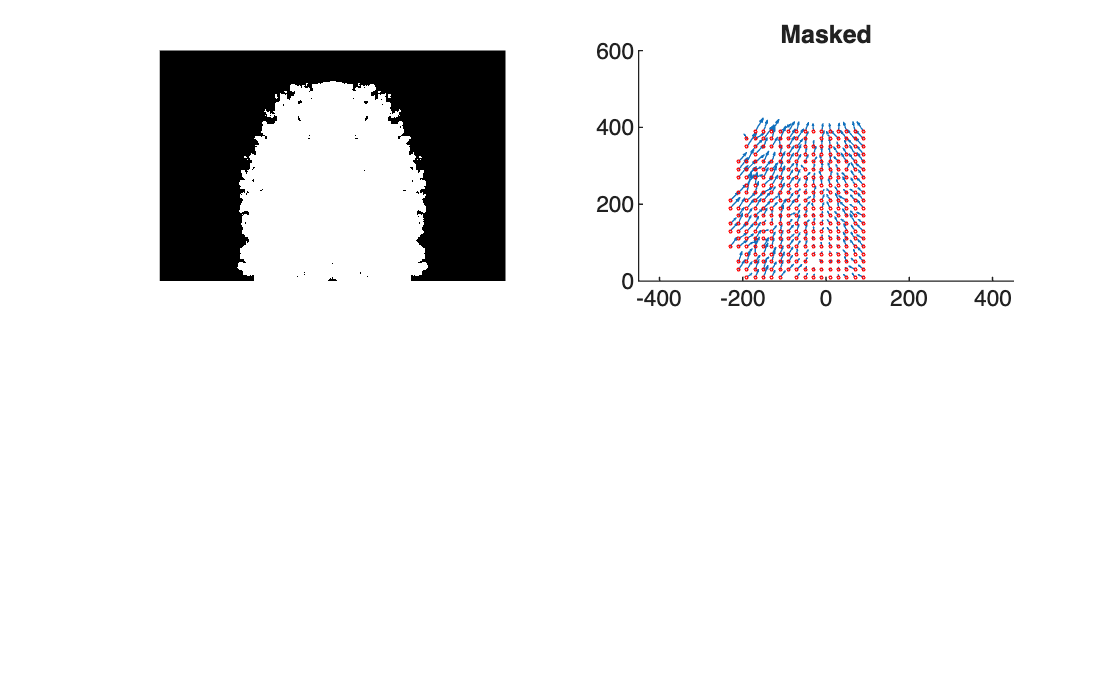

Error using stream2
U,V must all be size 2x2 or greater.

gene_name = filename(1:(strfind(filename, '_map') - 1));
temp = load(fullfile(pathname, filename));
map_avg = temp.map_avg;
mean_map = map_avg.(['channel', num2str(ch)]).mean_map;
gene_mask = 0*mean_map;
gene_mask((abs(post_shift) + 1):end, :) = mean_map(1:(end - abs(post_shift)), :);
thres = 0.15;
gene_mask(gene_mask > thres) = 1;
gene_mask(gene_mask <= thres) = 0;
%gene_mask = imopen(gene_mask, strel(10));

[pos_R, pos_C] = ind2sub(size(gene_mask), find(gene_mask));
rc_grid_data = 0*sym_avg_grid_data;
rc_grid_data(:, 2) = sym_avg_grid_data(:, 1) + size(gene_mask, 2)/2;
rc_grid_data(:, 1) = size(gene_mask, 1) - sym_avg_grid_data(:, 2);

masked_idx = find(ismember(rc_grid_data, [pos_R, pos_C], 'rows'));
f3 = figure; 
subplot(2, 2, 1); imshow(gene_mask, []);
ax2 = subplot(2, 2, 2); hold on;
quiver(scale_factor*sym_avg_grid_data(masked_idx, 1), scale_factor*sym_avg_grid_data(masked_idx, 2), sym_avg_disp_on_grid(masked_idx , 1), sym_avg_disp_on_grid(masked_idx , 2), 2);
plot(scale_factor*sym_avg_grid_data(masked_idx, 1), scale_factor*sym_avg_grid_data(masked_idx, 2), 'ro', 'MarkerSize', 1);
title('Masked')
xlim(scale_factor*[-450 450])
ylim(scale_factor*[0 600])
saveas(f3, fullfile(exp_dir, 'Plots', ['E1_grid_masked_by_sox19a.svg'])